# TP1: Transformaciones, locomoción y sensado

# Robotica Móvil: un enfoque probabilistico(86.48)

# Alumno:Brian Alex Fuentes Acuña.

# Padrón: 101785.

%clc; clear all; close all;

## 1. Transformaciones 2D y matrices afines

* 1. Estando el robot en la pose *$x_1 = (x_1, y_1, \theta _1)^T$*, detecta un obstaculo p en la posicion *

$(p_x, p_y)$* con respecto a su propia terna de referencia. *

*Usar la matriz *$T_1$* para expresar las coordenadas de p con respecto a la terna global.*

%Dado que no se dan valores nomericos se procede a resolverlo en forma
%simbolica.
syms theta1 x1 y1 px py
assume([px py], 'real')
assume([x1 y1], 'real')


$p= \pmatrix{px \cr px \cr 1}$ sera la coordenada generalizada del obtaculo respecto de la terna del robot

$T_1= \pmatrix{cos(\theta_1) & -sen(\theta_1)  & x_1\cr sen(\theta_1) & cos(\theta_1) & y1\cr 0 & 0 & 1}$será la matriz que roto-traslación que me pasa las coordenadas del robot a las coordenadas globales.

Entonces si se quiere la posición del obstaculo **p** respecto de la terna global sera:


$$p_{gbl}= T_1 .p= \pmatrix{cos(\theta) & -sen(\theta)  & x_1\cr sen(\theta) & cos(\theta) & y1\cr 0 & 0 & 1}\pmatrix{p_x\cr py\cr 1}
= \pmatrix{ x_1 + p_x.cos(\theta _1) - p_ysen(\theta_1) \cr
 y_1 + p_y.cos(\theta_1) + p_x.sen(\theta_1) \cr
                                    1}$$


tener en cuenta que se uba una posicion extendida, en realidad el resultado seria

$t=
\pmatrix{ x_1 + p_x.cos(\theta _1) - p_ysen(\theta_1) \cr
 y_1 + p_y.cos(\theta_1) + p_x.sen(\theta_1) }
$ la primer y segunda fila de **p**, de ahora en adelante se referirá a **p** en vez de **t** pero se debe entender que se refiere solo a la primer y segunda fila.

esto tambien se puede hacer en codigo:

%posicion del robot respecto de la terna global
p= [px py 1]';
%posicion del robot respecto de la terna global
T1= RoTrs(theta1, [x1 y1]')

$$T1 = \left(\begin{array}{ccc} \cos\left(\theta_{1}\right) & -\sin\left(\theta_{1}\right) & x_{1}\\ \sin\left(\theta_{1}\right) & \cos\left(\theta_{1}\right) & y_{1}\\ 0 & 0 & 1 \end{array}\right)$$

%posicion del obstaculo respecto de la terna global
p_gbl= T1*p

$$p\_gbl = \left(\begin{array}{c} x_{1}+\mathrm{px}\,\cos\left(\theta_{1}\right)-\mathrm{py}\,\sin\left(\theta_{1}\right)\\ y_{1}+\mathrm{py}\,\cos\left(\theta_{1}\right)+\mathrm{px}\,\sin\left(\theta_{1}\right)\\ 1 \end{array}\right)$$

*2. Dada las coordenadas de un obstaculo en la terna global, ¿como pueden calcularse las coordenadas de dicho obstaculo que el robot va a medir en su propia terna?*

**RTA2:**

 Busco la matriz inversa de roto-traslacion que me lleve lo medido desde la terna global a la terna del robot.

Esto seria la inversa de T1 el cual se puede escribir en general:

$A^{-1}= \pmatrix{R^T & -R^T t \cr 0 & 1}$donde **R** es mi matriz de rotacion y **t** es la posicion.

${T_1}^{-1}= \pmatrix{cos(\theta _1) &sen(\theta_1) & y_1.sen(\theta_1) - x_1.cos(\theta_1)\cr -sen(\theta_1) & cos(\theta_1) &-y_1.cos(\theta_1) - x_1.sen(\theta_1)\cr 0 & 0 & 1}$entonces para obtener las coordenas del obstaculo respecto de la terna del robot:


$$p= {T_1}^{-1}.p_{gbl}= \pmatrix{cos(\theta _1) &sen(\theta_1) & y_1.sen(\theta_1) - x_1.cos(\theta_1)\cr -sen(\theta_1) & cos(\theta_1) &-y_1.cos(\theta_1) - x_1.sen(\theta_1)\cr 0 & 0 & 1}
\pmatrix{p_{xG} \cr p_{yG} \cr 1}$$


(tener en cuenta que mi posicion t seria la 1er y 2da fila de p)

podemos corroborarlo con codigo, deberia poder recuperar **p** :

%la inversa de A se lo calcula directamente.
p_rbt= simplify(T1\p_gbl) %inv(T1)*p_gbl

$$p\_rbt = \left(\begin{array}{c} \mathrm{px}\\ \mathrm{py}\\ 1 \end{array}\right)$$

*3. El robot se mueve a una nueva pose *$x_2 = (x_2, y_2, \theta _2)^T$* en la terna global. Encontrar la matriz de transformación *$T_{12}
$* que representa la nueva pose con respecto a *$x_1$*.*

**RTA_3:**

Esto se piensa asi: se proyecta las nuevas ternas de $X_2$ en $X_1$ y la transformacion que hace eso se llamará $T_{12}$, y la proyección de $X_2$ en la terna global la llamaremos$ T_2= \pmatrix{cos(\theta_2) & -sen(\theta_2)  & x_2\cr sen(\theta_2) & cos(\theta_2) & y_2\cr 0 & 0 & 1}$ entonces razonado se puede llegar a la siguiente relacion:

$T_2= T_1.T_{12}$ por lo cual el problema queda resuelto, dado que existe la inversa de $T_1$


$$T_{12}= {T_1}^{-1}T_2= \pmatrix{cos(\theta _1) &sen(\theta_1) & y_1.sen(\theta_1) - x_1.cos(\theta_1)\cr -sen(\theta_1) & cos(\theta_1) &-y_1.cos(\theta_1) - x_1.sen(\theta_1)\cr 0 & 0 & 1}
\pmatrix{cos(\theta_2) & -sen(\theta_2)  & x_2\cr sen(\theta_2) & cos(\theta_2) & y_2\cr 0 & 0 & 1}$$


comprobemos esto en codigo:

syms theta2 x2 y2
assume([x2 y2], 'real')
T2= RoTrs(theta2, [x2 y2]')

$$T2 = \left(\begin{array}{ccc} \cos\left(\theta_{2}\right) & -\sin\left(\theta_{2}\right) & x_{2}\\ \sin\left(\theta_{2}\right) & \cos\left(\theta_{2}\right) & y_{2}\\ 0 & 0 & 1 \end{array}\right)$$

T12= simplify(T1\T2) %inv(T1)*T2

$$T12 = \left(\begin{array}{ccc} \cos\left(\theta_{1}-\theta_{2}\right) & \sin\left(\theta_{1}-\theta_{2}\right) & x_{2}\,\cos\left(\theta_{1}\right)-x_{1}\,\cos\left(\theta_{1}\right)-y_{1}\,\sin\left(\theta_{1}\right)+y_{2}\,\sin\left(\theta_{1}\right)\\ -\sin\left(\theta_{1}-\theta_{2}\right) & \cos\left(\theta_{1}-\theta_{2}\right) & y_{2}\,\cos\left(\theta_{1}\right)-y_{1}\,\cos\left(\theta_{1}\right)+x_{1}\,\sin\left(\theta_{1}\right)-x_{2}\,\sin\left(\theta_{1}\right)\\ 0 & 0 & 1 \end{array}\right)$$

*4. Estando ahora el robot en la posición *$x_2$*, ¿dónde está el obstáculo p con respecto a la nueva terna local del robot? *

**RTA_4:**

Se podría calcular la matriz que pasa de la terna 1 a la 2 o ya teniendo el obstáculo en la terna global calcularla respecto de la terna 2 y sus variantes.

$p_2= {A_{12}}^{-1} p\\
p_2= {A_2}^{-1} p_{gbl}$ (tener en cuenta que mi posicion t seria la 1er y 2da fila de p)

Dependiendo el caso se podría utilizar la primera o la segunda.

p2_= simplify(T12\p)        %inv(T12)*p

$$p2\_ = \left(\begin{array}{c} x_{1}\,\cos\left(\theta_{2}\right)-x_{2}\,\cos\left(\theta_{2}\right)+y_{1}\,\sin\left(\theta_{2}\right)-y_{2}\,\sin\left(\theta_{2}\right)+\mathrm{px}\,\cos\left(\theta_{1}-\theta_{2}\right)-\mathrm{py}\,\sin\left(\theta_{1}-\theta_{2}\right)\\ y_{1}\,\cos\left(\theta_{2}\right)-y_{2}\,\cos\left(\theta_{2}\right)-x_{1}\,\sin\left(\theta_{2}\right)+x_{2}\,\sin\left(\theta_{2}\right)+\mathrm{py}\,\cos\left(\theta_{1}-\theta_{2}\right)+\mathrm{px}\,\sin\left(\theta_{1}-\theta_{2}\right)\\ 1 \end{array}\right)$$

p2=  simplify(T2\p_gbl)     %inv(T2)*p_gbl

$$p2 = \left(\begin{array}{c} x_{1}\,\cos\left(\theta_{2}\right)-x_{2}\,\cos\left(\theta_{2}\right)+y_{1}\,\sin\left(\theta_{2}\right)-y_{2}\,\sin\left(\theta_{2}\right)+\mathrm{px}\,\cos\left(\theta_{1}-\theta_{2}\right)-\mathrm{py}\,\sin\left(\theta_{1}-\theta_{2}\right)\\ y_{1}\,\cos\left(\theta_{2}\right)-y_{2}\,\cos\left(\theta_{2}\right)-x_{1}\,\sin\left(\theta_{2}\right)+x_{2}\,\sin\left(\theta_{2}\right)+\mathrm{py}\,\cos\left(\theta_{1}-\theta_{2}\right)+\mathrm{px}\,\sin\left(\theta_{1}-\theta_{2}\right)\\ 1 \end{array}\right)$$

%Notar que ambos resultados son equivalentes.

## 2. Sensado

%POSE robot
xr= 5; yr= -7; theta_r= -pi/4; % [m m rad/s]
%POSE LIDAR
xl= 0.2; yl=0.0; theta_l= pi;  % [m m rad/s]
%. La primera medición se toma para el ángulo α = −π/2(según la
% terna del sensor) y la última se toma para el ángulo α =π/2

*1. Graficar las mediciones en la terna de referencia del LIDAR.*

*Para ello hay que tener en cuenta el archivo "lasercan.dat" el cual contiene los archivos de lectura de un lidar, por lo que el archivo contiene  lecturas de distancia.*

entonces primero se cargan los datos:

%Los datos de Lidar son un array de lecturas de distancias
scan = load('laserscan.dat','-ascii');
%calculo los angulo correspondientes.
angle = linspace(-pi/2, pi/2, size(scan,2));

Se procede a graficar las posiciones en función de los del Angulo en un gráfico cartesiano para apreciar mejor los datos necesarios y en un gráfico polar para tener una mejor comprensión visual de lo que realmente sucede.

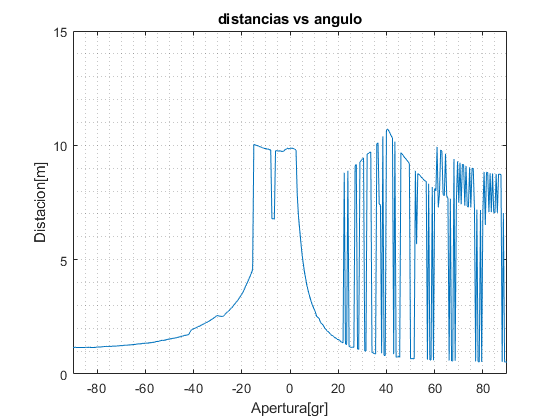

figure()
plot(angle*180/pi, scan,'-')
axis([-90 90 0 15])
title('distancias vs angulo')
xlabel('Apertura[gr]')
ylabel('Distacion[m]')
grid('minor')

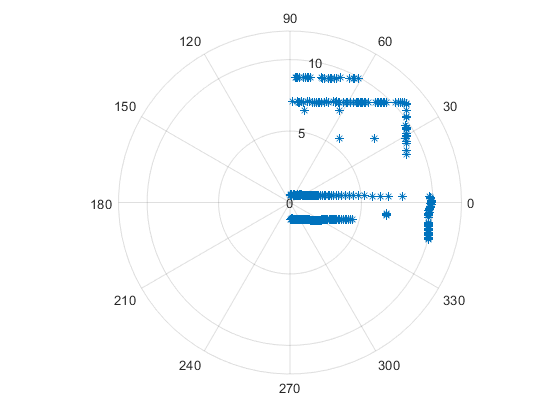


figure()
title('distancias vs angulo')
polarplot(angle,scan,'*')

%

*2. ¿Cómo podría interpretarse el entorno a partir de estas mediciones? *

**RTA:**

Un LIDAR devuelve la distancia de un objeto con respecto al LIDAR.

"La distancia al objeto se determina midiendo el tiempo de retraso entre la emisión del pulso y su detección a través de la señal reflejada".

Observando la imagen se puede ver que parece encontrarse en un pasillo, pero también puede detectar otro pasillo con características similares subiere entonces distintas paredes que pueden ser traspasadas por el láser del LIDAR y así poder ser detectados.

Se discute más adelante la interpretación espacial de los puntos medidos.

*3. Usar las transformaciones homogéneas para calcular y graficar: *

*a) La posición del robot en la terna global.*

T_0R= RoTrs(theta_r, [xr yr]')

T_0R =     0.7071    0.7071    5.0000
   -0.7071    0.7071   -7.0000
         0         0    1.0000


%
xrG= T_0R(1,3);
yrG= T_0R(2,3);

*b) La posición del LIDAR en la terna global.*

T_RL= RoTrs(theta_l, [xl yl]')

T_RL =    -1.0000   -0.0000    0.2000
    0.0000   -1.0000         0
         0         0    1.0000


T_0L= T_0R*T_RL

T_0L =    -0.7071   -0.7071    5.1414
    0.7071   -0.7071   -7.1414
         0         0    1.0000


%
xlG= T_0L(1,3);
ylG= T_0L(2,3);


*c) Las mediciones en la terna global.*

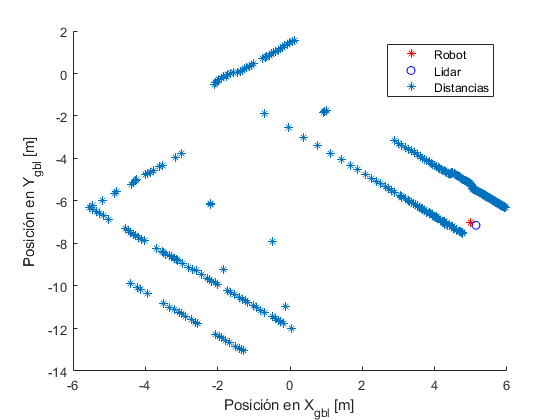

%creo vectores para las posiciones cartesianas respecto del lidar
xL=      zeros(1,size(scan,2));
yL=      zeros(1,size(scan,2));
%creo vectores para las posiciones cartesianas respecto de la terna Global
pos_G=      zeros(3,size(scan,2));

%Obtengo las posiciones cartesianas respecto de la terna Global.
for i= 1:size(scan,2)
    xL(i)= scan(i)*cos(angle(i));
    yL(i)= scan(i)*sin(angle(i));
    
    pos_G(:,i)= T_0L*[xL(i) yL(i) 1]';
end


figure()
hold on
plot(xrG,yrG, 'r*')
plot(xlG,ylG, 'bo')
plot(pos_G(1,:),pos_G(2,:),'*')
legend('Robot', 'Lidar', 'Distancias')
xlabel('Posición en X_{gbl} [m]')
ylabel('Posición en Y_{gbl} [m]')

Observar las imágenes, claramente se puede ver como graficando las distancias se observan las formas procedentes de los rebotes con los distintos objetos a la derecha parece estar en un pasillo con una pared sólida y una puerta cerrada.

Pero si vemos más allá, se puede ver otro pasillo con una menor densidad de puntos, lo cual sugiere que ha traspasado la primer "pared izquierda", es como si hubiera paneles de vidrio o alguna "pared" porosa que permita pasar los haces de luz y medir su distancia al LIDAR.

Pero en medio de los pasillos hay 4 puntos que llaman la atención, en principio se podría decir que es ruido, después de todo la luz proveniente del lidar puede rebotar en cualquier dirección, pero estos parecen estar ordenados sugiere que pueda ser otra cosa, como personas, o si se piensa que esto es una medición en una casa (con un pario interior) con paneles exteriores a un patio rodeado, podrían ser pequeños árboles y eso encajaría con las mediciones que tomo el LIDAR.

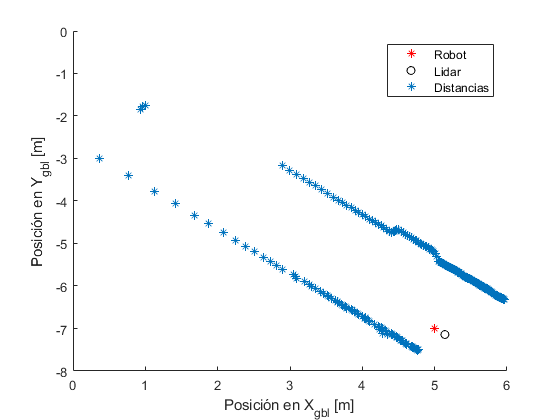

figure()
hold on
plot(xrG,yrG, 'r*')
plot(xlG,ylG, 'ko')
plot(pos_G(1,:),pos_G(2,:),'*')
legend('Robot', 'Lidar', 'Distancias')
xlabel('Posición en X_{gbl} [m]')
ylabel('Posición en Y_{gbl} [m]')
axis([0 6 -8 0])

 Ademas se puede observar la posicion en la que se encuentra el robot y el sensor LIDAR con su particular rotacion proveniente de la rotacion del robot respecto de la terna global, π/4.

Notar ademas que a la izquierda el pasillo parece terminar y hay unos puntos solitarios que bien podrian ser una columna

## 3. Accionamiento diferencial

*1. El encabezado de la función debe tener esta forma: function ****[x_n y_n theta n] = diffdrive(x, y, theta, v_l, v_r, t, l)**** donde**** x, y****, theta es la pose del robot,**** v_l**** y**** v_r**** son las velocidades de la rueda izquierda y derecha, ****t**** es el intervalo de tiempo en movimiento y ****l**** es la distancia entre ruedas del robot.*

* La salida de la función es una nueva pose del robot dada por ****x_n****, ****y_n,theta_n.*** 

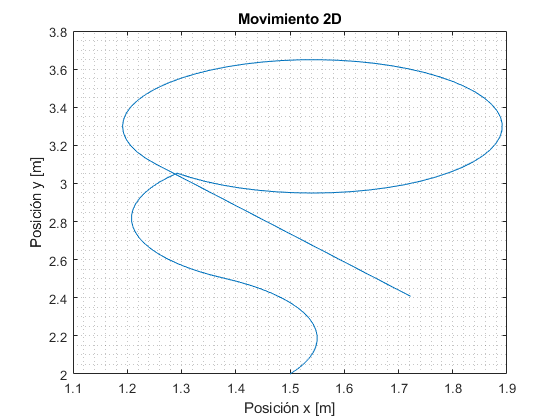

x= 1.5; y= 2.0; theta= pi/3; %[m m rad/s]
l= 0.5; %m

% a) c1 = (vl = 0,1m/s, vr = 0,5m/s, t = 2s)
% b) c2 = (vl = 0,5m/s, vr = 0,1m/s, t = 2s)
% c) c3 = (vl = 0,2m/s, vr = −0,2m/s, t = 2s)
% d) c4 = (vl = 0,1m/s, vr = 0,6m/s, t = 6s)
% e) c5 = (vl = 0,4m/s, vr = 0,4m/s, t = 2s)
C= [0.1  0.5 2;
    0.5  0.1 2;
    0.2 -0.2 2;
    0.1  0.6 6;
    0.4  0.4 2];

 [x_n, y_n, theta_n]= trayectoria(C, [1.5 2.0 pi/3], l, 0.1);
 figure()
 plot(x_n, y_n)
 title('Movimiento 2D')
grid('minor')
xlabel('Posición x [m]')
ylabel('Posición y [m]')

Para obtener lo pedido se ah creado la funcion *trayectoria* en donde hace uso de la funcion *diffdrive *para obtener los  puntos intermedios entre los intervalos de tiempos pedidos.

Para ello se usaron las ecuaciones vistas para el accionamiento diferencial, en donde particularmente se vieron singularidades para $v_r= v_l
$ que hace que $R-> \infty$  y w=0 lo que demboca en $x,y,\theta$ no cambien en el intervalo dado, y esto no es cierto dado que es el caso particular en que el robot se mueve linealmente.

Para ese caso entonces se hace uso de la integral de la velocidad y se lo deriva obteniendo el movimiento lineal para ese caso particular.

Nota: se usó el primer metodo pero tambien se implemento  *diffdrive2 *que hace uso solamente de las integrales de las velocidades y el resultado es el mismo. 

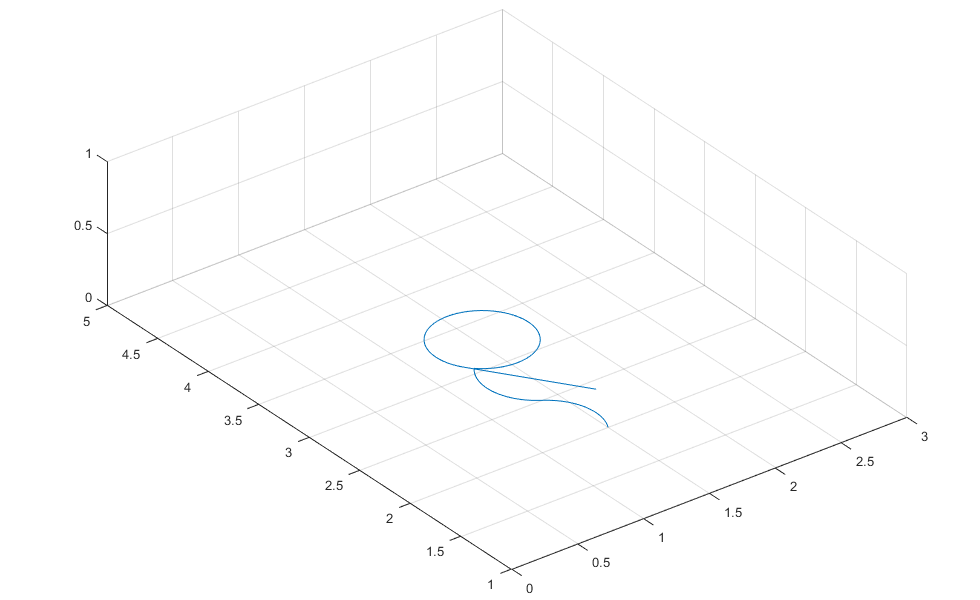

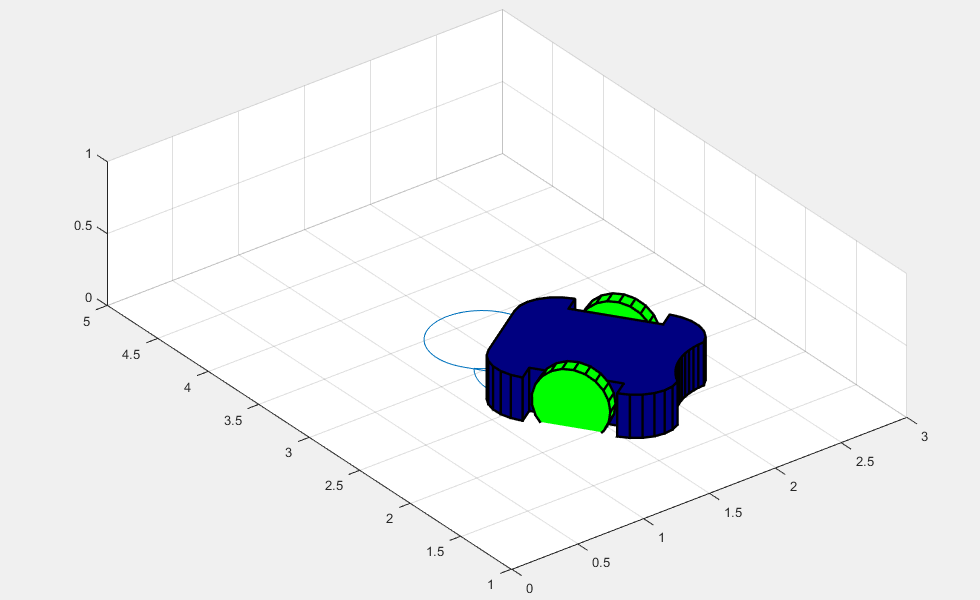

%%DE YAPA: usando unos scripts se puede simular un robot diferencial en 3D
%para correrlo fuera del LiveScript copiar y pega esta seccion en el ComandWindow
% o abrir la imagen en ventana y luego ejecutar.
%Nota: las dimensiones del robot son muy grandes, se puede modificar en el codigo correspondiente

fig=figure;
set(fig,'position',[10 60 980 600]);
axis square; cameratoolbar
axis([0 3 1 5 0 1]); grid on
MobileRobot;
%M1=MobilePlot(x_n(1),y_n(1),theta_n(1));
hold on, plot(x_n,y_n);

for i=1:length(x_n)
    
    delete (M1)
    M1=MobilePlot(x_n(i),y_n(i),theta_n(i)); hold on
    
    pause(0.1)
    
end

function [x_n, y_n, theta_n] = diffdrive(x, y, theta, v_l, v_r, dt, l)
   %Cuando vl=vr hay una indeterminacion R->inf W=0 y POSEn= [x; y; theta]
   %Lo cual no es correcto dado que ese es el caso en que el robot se mueve
   %en linea recta.
    if v_l==v_r
        v=            (v_r + v_l)/2;
        x_n  =        x + dt*v*cos(theta);
        y_n  =        y + dt*v*sin(theta);
        theta_n  =    theta;
    else
        R= l*(v_l + v_r)/(2*(v_r - v_l));   
        w= (v_r - v_l)/l;
    
        ICC= [x-R*sin(theta), y + R*cos(theta)];  
        
        POSEn=[cos(w*dt) -sin(w*dt) 0; sin(w*dt) cos(w*dt) 0;0 0 1]*[x-ICC(1,1); y-ICC(1,2); theta]+[ICC(1,1); ICC(1,2); w*dt];
    
        x_n  =        POSEn(1,1);
        y_n  =        POSEn(2,1);
        theta_n  =    POSEn(3,1);
    end
    %
end

function [x_n, y_n, theta_n] = diffdrive2(x, y, theta, v_l, v_r, dt, l)
    if v_l==v_r
        R=10e20;  %esto será mi infinito(RngMatlab: 10e-308 a 10e+308)
    else
        R= l*(v_l + v_r)/(2*(v_r - v_l));
    end
    w= (v_r - v_l)/l;
    v= (v_r + v_l)/2;
    %v=w*R;
    
    x_n  =        x+dt*v*cos(theta);
    y_n  =        y+dt*v*sin(theta);
    theta_n  =    theta+dt*w;  
end

function R = Rot(theta)
R= [cos(theta) -sin(theta);
    sin(theta) cos(theta)];
end

function RT = RoTrs(theta, pos)
RT= [Rot(theta) pos(:);
    zeros(1,2) 1.0];
end


%%
function [x_n, y_n, theta_n]= trayectoria(C, X_0, l, dt)
 %[x_n, y_n, theta_n,t_n]= trayectoria (C, X_0,l,dt)
 %ej: X_0=[x0= 1.5; y0= 2.0; theta_0= pi/3]
 %Genera puntos intermedio de trayectorias correspondientes a los puntos brindados por C, cada dt.
  
n_max= size(C,1);
 %inicializo.
x_n=     X_0(1);
y_n=     X_0(2);
theta_n= X_0(3);
idx=2;
for i=1:n_max
    %Calculo el largo de los vectores
    v_large=    round(C(i,3)/dt);
    %creo vectores auxialires de larlo v_large.
    aux_x=      zeros(1, v_large);
    aux_y=      aux_x;
    aux_theta=  aux_x;
    %Concateno vectores.
    x_n=      horzcat(x_n, aux_x);
    y_n=      horzcat(y_n, aux_y);
    theta_n=  horzcat(theta_n, aux_theta);
    %Completo la trayectoria
    for k= idx:(v_large + idx)
   [x_n(k), y_n(k), theta_n(k)] = diffdrive(x_n(k-1), y_n(k-1), theta_n(k-1), C(i,1), C(i,2), dt, l);       
    end
    
    
    if idx~=2
        idx= idx + v_large+1;
    else
        idx= v_large+1;
    end
end

end


